Optional Exam 2

Kathryn Atherton

ABE 30100

04/05/2019

TAOCO has discovered that a valuable pharmaceutical product (Bazingium) can be made by fermentation, which is a process involving a pre-defined complex mixture of reactants (yeast extract, various pH buffers, glucose, various co-factors), as well as cell growth/death. Since the pathways and reactants are unknown/so complex, it does not make sense to create a model based on reactant concentrations. Instead, the concentration of product, B(t), is simply measured vs. time in a batch reactor (see data). 

As a TAOCO engineer, you are asked to create a continuous, steady state process to make Bazingium. There happens to be an available 2500 L stirred tank reactor which has ideal mixing behavior such that given a steady volumetric flowrate (q), the outlet product concentration (B) is the same as the product concentration (B) in the tank at steady state (see drawing). 

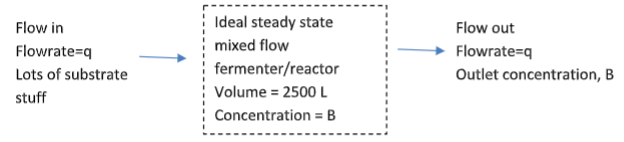

As a bright young engineer, you realize that to maximize income, you will need to operate the reactor is such a way as to maximize the production of Bazingium, i.e. moles produced per hr.

% data
time = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15]; % [h]
B = [0, 2, 4, 8, 15, 30, 50, 75, 100, 117, 122, 124, 125, 125, 125, 125]; % [mol/L]

**Part A**

Create a cubic spline model for the batch reaction data (concentration of B vs. time). Provide an appropriate plot showing the model and the data. (Does your model look like a batch fermentation profile?)

[S, f] = cubic_spline(time, B);

Valid from x = 0.0000 to 1.0000

$$f = 2.1219\,x-0.12193\,x^{3}$$

Valid from x = 1.0000 to 2.0000

$$f = \left(\begin{array}{cc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 \end{array}\right)$$

Valid from x = 2.0000 to 3.0000

$$f = \left(\begin{array}{ccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 \end{array}\right)$$

Valid from x = 3.0000 to 4.0000

$$f = \left(\begin{array}{cccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 \end{array}\right)$$

Valid from x = 4.0000 to 5.0000

$$f = \left(\begin{array}{ccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 \end{array}\right)$$

Valid from x = 5.0000 to 6.0000

$$f = \left(\begin{array}{cccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 \end{array}\right)$$

Valid from x = 6.0000 to 7.0000

$$f = \left(\begin{array}{ccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 \end{array}\right)$$

Valid from x = 7.0000 to 8.0000

$$f = \left(\begin{array}{cccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 \end{array}\right)$$

Valid from x = 8.0000 to 9.0000

$$f = \left(\begin{array}{ccccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 & 22.357\,x-4.0576\,{\left(x-8.0\right)}^{2}-1.2991\,{\left(x-8.0\right)}^{3}-78.854 \end{array}\right)$$

Valid from x = 9.0000 to 10.0000

$$f = \left(\begin{array}{cccccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 & 22.357\,x-4.0576\,{\left(x-8.0\right)}^{2}-1.2991\,{\left(x-8.0\right)}^{3}-78.854 & 10.344\,x-7.955\,{\left(x-9.0\right)}^{2}+2.6109\,{\left(x-9.0\right)}^{3}+23.903 \end{array}\right)$$

Valid from x = 10.0000 to 11.0000

$$f = \left(\begin{array}{ccccccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 & 22.357\,x-4.0576\,{\left(x-8.0\right)}^{2}-1.2991\,{\left(x-8.0\right)}^{3}-78.854 & 10.344\,x-7.955\,{\left(x-9.0\right)}^{2}+2.6109\,{\left(x-9.0\right)}^{3}+23.903 & 2.2668\,x-0.12231\,{\left(x-10.0\right)}^{2}-0.14448\,{\left(x-10.0\right)}^{3}+99.332 \end{array}\right)$$

Valid from x = 11.0000 to 12.0000

$$f = \left(\begin{array}{cccccccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 & 22.357\,x-4.0576\,{\left(x-8.0\right)}^{2}-1.2991\,{\left(x-8.0\right)}^{3}-78.854 & 10.344\,x-7.955\,{\left(x-9.0\right)}^{2}+2.6109\,{\left(x-9.0\right)}^{3}+23.903 & 2.2668\,x-0.12231\,{\left(x-10.0\right)}^{2}-0.14448\,{\left(x-10.0\right)}^{3}+99.332 & 1.5887\,x-0.55575\,{\left(x-11.0\right)}^{2}-0.032988\,{\left(x-11.0\right)}^{3}+106.52 \end{array}\right)$$

Valid from x = 12.0000 to 13.0000

$$f = \left(\begin{array}{ccccccccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 & 22.357\,x-4.0576\,{\left(x-8.0\right)}^{2}-1.2991\,{\left(x-8.0\right)}^{3}-78.854 & 10.344\,x-7.955\,{\left(x-9.0\right)}^{2}+2.6109\,{\left(x-9.0\right)}^{3}+23.903 & 2.2668\,x-0.12231\,{\left(x-10.0\right)}^{2}-0.14448\,{\left(x-10.0\right)}^{3}+99.332 & 1.5887\,x-0.55575\,{\left(x-11.0\right)}^{2}-0.032988\,{\left(x-11.0\right)}^{3}+106.52 & 0.37828\,x-0.65471\,{\left(x-12.0\right)}^{2}+0.27643\,{\left(x-12.0\right)}^{3}+120.46 \end{array}\right)$$

Valid from x = 13.0000 to 14.0000

$$f = \left(\begin{array}{cccccccccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 & 22.357\,x-4.0576\,{\left(x-8.0\right)}^{2}-1.2991\,{\left(x-8.0\right)}^{3}-78.854 & 10.344\,x-7.955\,{\left(x-9.0\right)}^{2}+2.6109\,{\left(x-9.0\right)}^{3}+23.903 & 2.2668\,x-0.12231\,{\left(x-10.0\right)}^{2}-0.14448\,{\left(x-10.0\right)}^{3}+99.332 & 1.5887\,x-0.55575\,{\left(x-11.0\right)}^{2}-0.032988\,{\left(x-11.0\right)}^{3}+106.52 & 0.37828\,x-0.65471\,{\left(x-12.0\right)}^{2}+0.27643\,{\left(x-12.0\right)}^{3}+120.46 & 0.17459\,{\left(x-13.0\right)}^{2}-0.10184\,x-0.072746\,{\left(x-13.0\right)}^{3}+126.32 \end{array}\right)$$

Valid from x = 14.0000 to 15.0000

$$f = \left(\begin{array}{ccccccccccccccc} 2.1219\,x-0.12193\,x^{3} & 1.7561\,x-0.36579\,{\left(x-1.0\right)}^{2}+0.60965\,{\left(x-1.0\right)}^{3}+0.24386 & 2.8535\,x+1.4632\,{\left(x-2.0\right)}^{2}-0.31667\,{\left(x-2.0\right)}^{3}-1.707 & 4.8298\,x+0.51315\,{\left(x-3.0\right)}^{2}+1.657\,{\left(x-3.0\right)}^{3}-6.4895 & 10.827\,x+5.4842\,{\left(x-4.0\right)}^{2}-1.3114\,{\left(x-4.0\right)}^{3}-28.309 & 17.861\,x+1.5499\,{\left(x-5.0\right)}^{2}+0.58877\,{\left(x-5.0\right)}^{3}-59.307 & 22.727\,x+3.3162\,{\left(x-6.0\right)}^{2}-1.0436\,{\left(x-6.0\right)}^{3}-86.365 & 26.229\,x+0.18535\,{\left(x-7.0\right)}^{2}-1.4143\,{\left(x-7.0\right)}^{3}-108.6 & 22.357\,x-4.0576\,{\left(x-8.0\right)}^{2}-1.2991\,{\left(x-8.0\right)}^{3}-78.854 & 10.344\,x-7.955\,{\left(x-9.0\right)}^{2}+2.6109\,{\left(x-9.0\right)}^{3}+23.903 & 2.2668\,x-0.12231\,{\left(x-10.0\right)}^{2}-0.14448\,{\left(x-10.0\right)}^{3}+99.332 & 1.5887\,x-0.55575\,{\left(x-11.0\right)}^{2}-0.032988\,{\left(x-11.0\right)}^{3}+106.52 & 0.37828\,x-0.65471\,{\left(x-12.0\right)}^{2}+0.27643\,{\left(x-12.0\right)}^{3}+120.46 & 0.17459\,{\left(x-13.0\right)}^{2}-0.10184\,x-0.072746\,{\left(x-13.0\right)}^{3}+126.32 & 0.029098\,x-0.043647\,{\left(x-14.0\right)}^{2}+0.014549\,{\left(x-14.0\right)}^{3}+124.59 \end{array}\right)$$

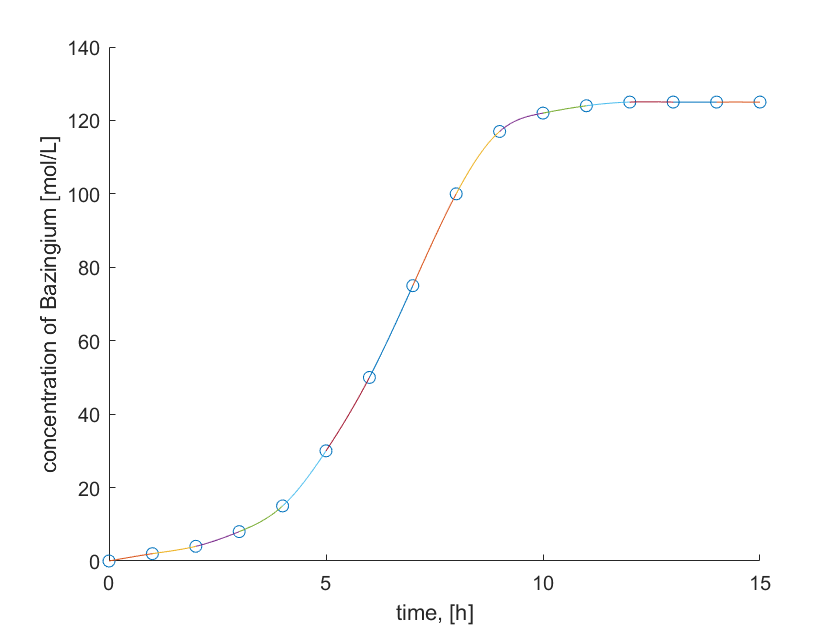

xlabel('time, [h]')
ylabel('concentration of Bazingium [mol/L]')
hold off

The plot does look like a batch fermentation profile because there is the beginning section where the cells are just beginning to grow, so not much of B is produced (about t = 0 to t = 3 hours), then there is the rapid growth phase where the cells grow and divide while producing high amounts of the product (about t = 3 to t = 9 hours), and at the end, all of the substrate has been consumed by the cells, so there is no more growth (about t = 9 to t = 15 hours). 

**Part B**

Using your spline model, determine the rate of reaction of Bazingium as a function of time, r(t), and provide an appropriate plot of the rate vs. time, i.e. r(t) vs. t. (Does your rate model make sense based on part A?)

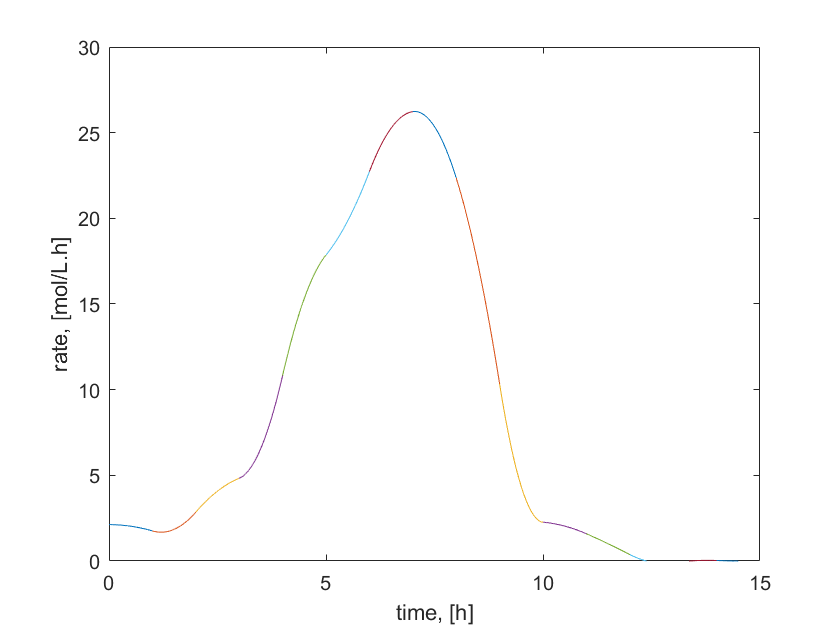

rate = diff(f);
for i = 1:(length(time) - 1)
    ezplot(rate(i), [time(i), time(i + 1)])
    hold on
end
hold off
xlim([0,15])
ylim([0,30])
title(' ')
xlabel('time, [h]')
ylabel('rate, [mol/L.h]')

My rate model does make sense based on part A because the maximum rate is in the middle of the rapid growth phase (between t = 3 and t = 9 hours). 

**Part C**

Using your model and a product mass balance around the reactor, determine the operating condition that maximizes the production of Bazingium and calculate the maximum Bazingium production rate (mol/hr). (Suggestions: Might be beneficial to check your units/dimensions. Think about how parts A and B might be related to the production of Bazingium. What is the operating parameter for this process, i.e. what can you as the engineer change? How is the Bazingium production calculated?)

Product mass balance: In - Out + Generation - Consumption = Accumulation

- In: 0, assume no Bazingium initially enters the reactor

- Out: B * q [mol/L * L/h = mol/h], here B is the cubic spline function (f) developed in part A.

- Generation: r(t) * V [mol/L.h * L = mol/h], here r(t) is the cubic spline function (rate) developed in part B.

- Consumption: 0, assume Bazingium is not consumed by another reaction prior to leaving the reactor. 

Accumulation = 0 - B * q + r(t) * V - 0 = rate * V - f * q

As an engineer, I can change the q (volumetric flow rate) of the reactor. 

The Bazingium production is calculated by taking the integral under the Accumulation curve. 

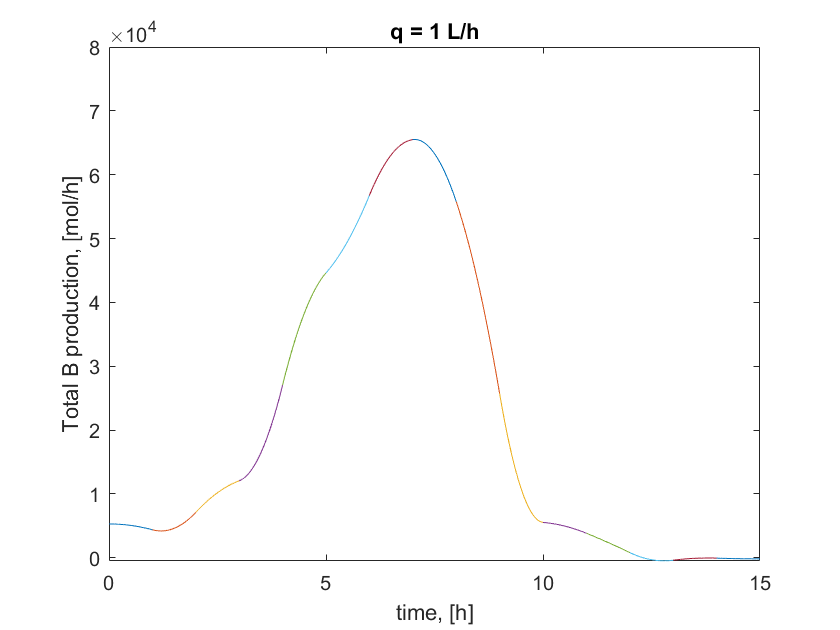

V = 2500; % [L]
q = 1; % [L/h]
production = 0;
for i = 1:(length(time) - 1)
    Accumulation = rate(i) .* V - f(i) .* q;
    production = production + int(Accumulation, x, time(i), time(i + 1));
    ezplot(Accumulation, [time(i), time(i + 1)])
    hold on
end
ylim([-500,80000])
xlim([0,15])
title('q = 1 L/h')
xlabel('time, [h]')
ylabel('Total B production, [mol/h]')
hold off

production % mol

$$production = 311422.0$$

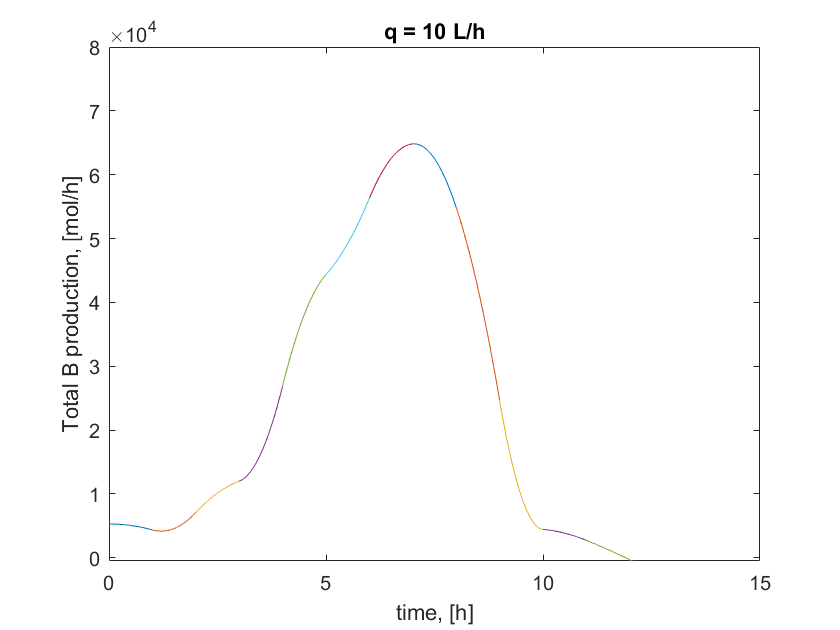

q = 10; % [L/h]
production = 0;
for i = 1:(length(time) - 1)
    Accumulation = rate(i) .* V - f(i) .* q;
    production = production + int(Accumulation, x, time(i), time(i + 1));
    ezplot(Accumulation, [time(i), time(i + 1)])
    hold on
end
ylim([-500,80000])
xlim([0,15])
title('q = 10 L/h')
xlabel('time, [h]')
ylabel('Total B production, [mol/h]')
hold off

production % mol

$$production = 301666.0$$

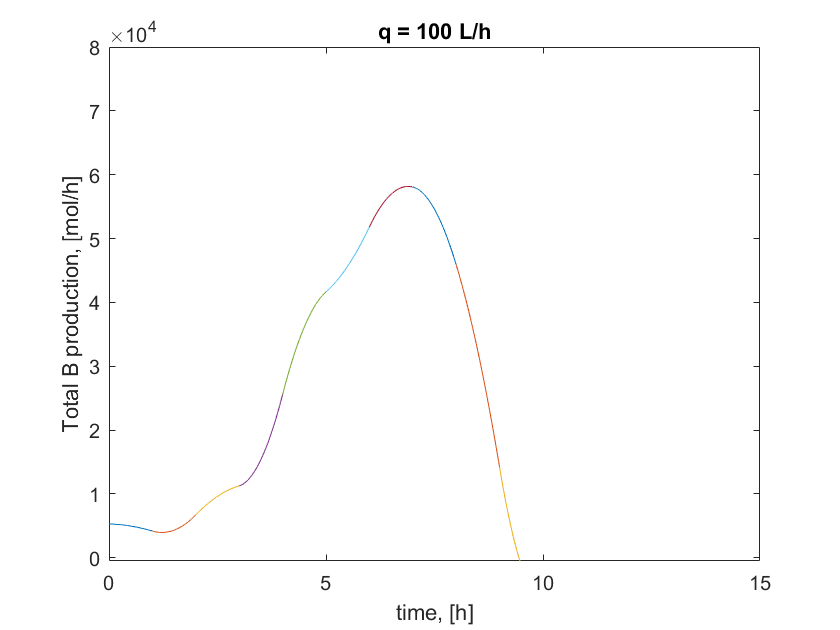

q = 100; % [L/h]
production = 0;
for i = 1:(length(time) - 1)
    Accumulation = rate(i) .* V - f(i) .* q;
    production = production + int(Accumulation, x, time(i), time(i + 1));
    ezplot(Accumulation, [time(i), time(i + 1)])
    hold on
end
ylim([-500,80000])
xlim([0,15])
title('q = 100 L/h')
xlabel('time, [h]')
ylabel('Total B production, [mol/h]')
hold off

production % mol

$$production = 204033.0$$

This finds that a lower q (flow rate) ensures maximum B production as it prevents a "washout" condition in which the flowrate removes all of the cells and product before the cells are complete with the fermentation process (assuming that the exiting flow contains B, cells, and substrate).

The maximum production rate in mol/h can be found with a root finding method on the accumulation function. I will use the accumulation function with a q of 1 mol/L to find the time at which the rate is at its maximum. It appears that the rate is at a maximum at aboout t = 7 hours. 

Accumulation = rate(8) .* V - f(8) .* 1;
x_root = newton_raphson(diff(Accumulation), 7, 0.001)

x_root = 7.0424

max = double(subs(Accumulation,x,x_root))

max = 65517

The maximum production rate occurs at time 7.0424 hours. The maximum production rate (at this time) is 65517 mol/h.

**Functions**

function [S, f] = cubic_spline(x1, y)
m = length(x1);
n = length(y);

if m ~= n
    error('Error: x and y have different dimensions.');
elseif m < 3
    error('Error: not enough points to create a cubic spline.');
else
    scatter(x1,y);
    hold on;
    [A, B, C, D] = spline_coeff(x1,y); 
    S = zeros(m, 1);
    for i = 1:m-1
        a = double(A(i));
        b = double(B(i));
        c = double(C(i));
        d = double(D(i));
        digits(5)
        syms x
        fprintf('Valid from x = %.4f to %.4f', x1(i), x1(i + 1))
        f(i) = vpa(a) + (vpa(b) * (x - vpa(x1(i)))) + (vpa(c) * ((x - vpa(x1(i))) ^ 2)) + ...
            (vpa(d) * ((x - vpa(x1(i))) ^ 3))
        vals = x1(i):0.01:x1(i+1);
        x = vals;
        plot(vals, subs(f(i)));
        hold on;
    end
end
end

function H = h_matrix(x)
n = length(x);
H = zeros(n,n);
H(1,1) = 1;
H(n,n) = 1;
for i = 2:n-1
    for j = 1:n
        if j == i
            H(i, j) = double(2 * ((x(i) - x(i - 1)) + (x(i + 1) - x(i))));
            H(i, j - 1) = double(x(i) - x(i - 1));
            H(i, j + 1) = double(x(i + 1) - x(i));
        end
    end
end
end

function C = k_matrix(x, y)
m = length(x);
n = length(y);
if m ~= n
    error("Error: x and y have different dimensions.");
else
    K = zeros(m,1);
    for i = 2:m-1
        h1 = double(x(i + 1) - x(i));
        h0 = double(x(i) - x(i - 1));
        a2 = double(y(i + 1));
        a1 = double(y(i));
        a0 = double(y(i - 1));
        K(i,1) = double(((3 * (a2 - a1)) / h1) - ((3 * (a1 - a0)) / h0)); 
    end
    H = h_matrix(x);
    C = H\K;
end
end

function [A, B, C, D] = spline_coeff(x, y)
m = length(x);
n = length(y);
if m ~= n
    error('Error: x and y have different dimensions.');
else
    B = zeros(length(y)-1,1);
    D = B;
    C = k_matrix(x,y);
    A = y;
    for i = 1:m-1
        h = (x(i + 1) - x(i));
        B(i,1) = double(((A(i + 1) - A(i)) / h) - (((C(i + 1) + 2 * C(i)) * h) / 3));
        D(i,1) = double((C(i + 1) - C(i)) / (3 * h));
    end
end
end

function x_root = newton_raphson(f, x1, error_tol)
    x      = x1;
    zero   = double(subs(f));                                  % sets zero to the value of the 
                                                                   % function at the given x 
                                                                   % point
    x_root = x1;                                               % renames input x value
    while abs(zero) > error_tol                                % checks to see if another 
                                                                   % iteration should be 
                                                                   % performed
        x     = x_root;
        slope = double(subs(diff(f)));                         % finds the slope of the function 
                                                                   % at the given point
        if slope == 0                                          % checks for a minimum or maximum
            fprintf('Error: stuck at minimum or maximum of function.\n')
            zero   = 0;                                        % breaks the while loop so that the 
                                                                   % function doesn't go on forever
            x_root = 'N/A'; 
        else
            b      = zero - slope * x_root;                    % finds the b of the function 
                                                                   % y = mx + b
            x_root = double(-b / slope);                       % finds the new x where y = 0 for 
                                                                   % the linear function
            x      = x_root;
            zero   = double(subs(f));                          % finds the value of the function 
                                                                   % at the x found above
        end
    end
    if x_root == 'N/A'                                         % changes the zero value to N/A in 
                                                                   % the case that a maximum was 
                                                                   % found after loop break
        zero  = 'N/A';
    end
end